% From https://www.aquarianaudio.com/as-1-hydrophone.html
% Frequency data (Hz), phase (deg) and magnitude (Ohm)
freq = [1000, 2000, 5000, 10000, 15000, 20000, 25000, 30000, 35000, ...
        40000, 45000, 50000, 55000, 60000];
phase_deg = [-83, -88, -87, -88, -89, -89, -89.5, -90, -90.5, -91, ...
             -87, -89, -88, -88];
mag = [18500, 9000, 3500, 1600, 1000, 1000, 750, 500, 450, 400, ...
       380, 360, 320, 300];

% Convert measured data to complex impedance:
phase_rad = deg2rad(phase_deg);
Z_meas = mag .* exp(1j*phase_rad);
w_data = 2*pi*freq;

% Define the hydrophone equivalent model:
%{
NOTES ON THE MODEL

          Rs
Vin o---/\/\---+----> Measure Z
              |
              Ls
              U
              |
              +----+----+
                   |    |
                  Rp   Cp
                  /     |
                  \    ===
                  /     |
                  |     GND
                  |
                 GND

w = 2*pi*f

Resistor: 

%}
%   Z_hydro = Rs + j*w*Ls + 1/(1/Rp + j*w*Cp)
model_fun = @(p, w) p(1) + 1j*w*p(2) + 1 ./ (1/p(3) + 1j*w*p(4));
% Cost function and optimization:
cost_fun = @(p) sum(abs(model_fun(p, w_data) - Z_meas).^2);
p0 = [100, 1e-3, 1000, 1e-9]; % Initial guess: [Rs, Ls, Rp, Cp]
opts = optimset('Display','iter');
p_opt = fminsearch(cost_fun, p0, opts);

 
 Iteration   Func-count         f(x)         Procedure
     0            1      4.51189e+08         
     1            5      4.50943e+08         initial simplex
     2            7      4.49849e+08         expand
     3            8      4.49849e+08         reflect
     4           10      4.49188e+08         expand
     5           12      4.48146e+08         expand
     6           14      4.46857e+08         expand
     7           15      4.46857e+08         reflect
     8           17      4.45163e+08         expand
     9           18      4.45163e+08         reflect
    10           20      4.44943e+08         reflect
    11           22      4.44585e+08         expand
    12           23      4.44585e+08         reflect
    13           24      4.44585e+08         reflect
    14           26      4.44585e+08         contract inside
    15           27      4.44585e+08         reflect
    16           29      4.44457e+08         reflect
    17           30      4.44457e+08   


% Extract optimized parameters:
Rs = p_opt(1);
Ls = p_opt(2);
Rp = p_opt(3);
Cp = p_opt(4);
fprintf('Optimized Hydrophone Parameters:\n');

Optimized Hydrophone Parameters:


fprintf('  Rs = %.2f ohm\n', Rs);

  Rs = 2.95 ohm


fprintf('  Ls = %.2e H\n', Ls);

  Ls = 1.67e-04 H


fprintf('  Rp = %.2f ohm\n', Rp);

  Rp = 155342.14 ohm


fprintf('  Cp = %.2e F\n', Cp);

  Cp = 8.62e-09 F


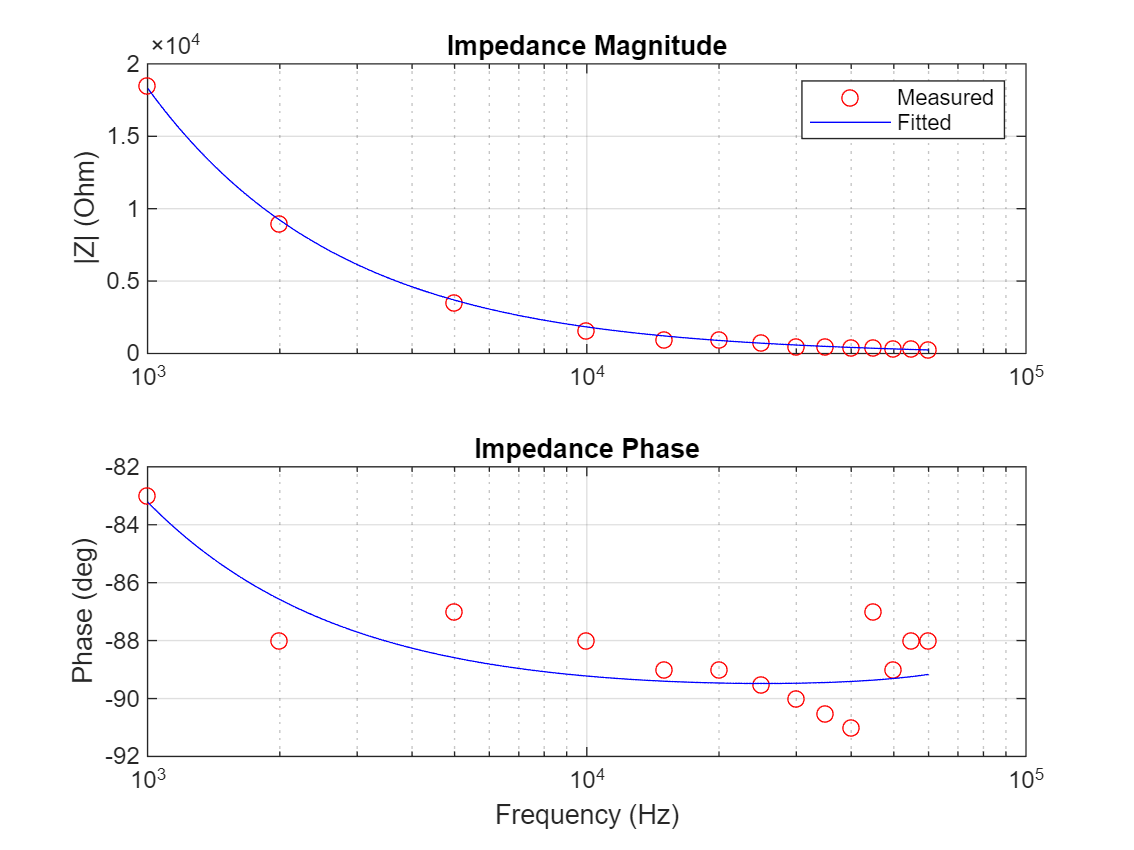


% Plot measured vs. fitted impedance (magnitude and phase)
f_interp = logspace(log10(min(freq)), log10(max(freq)), 500);
w_interp = 2*pi*f_interp;
Z_fit = model_fun(p_opt, w_interp);
figure;
subplot(2,1,1);
semilogx(freq, abs(Z_meas), 'ro', f_interp, abs(Z_fit), 'b-');
ylabel('|Z| (Ohm)');
title('Impedance Magnitude'); legend('Measured','Fitted'); grid on;
subplot(2,1,2);
semilogx(freq, phase_deg, 'ro', f_interp, rad2deg(angle(Z_fit)), 'b-');
xlabel('Frequency (Hz)'); ylabel('Phase (deg)');
title('Impedance Phase'); grid on;


% Define the hydrophone impedance as a function handle (for simulation):
hydrophone_Z = @(w) Rs + 1j*w*Ls + 1./(1/Rp + 1j*w*Cp);


%% ===== Impedance Matching: Canceling the Hydrophone Reactance =====
% Fundamental frequency:
f0 = 20e3;   % 20 kHz fundamental
w0 = 2*pi*f0;

% Evaluate the hydrophone impedance at 20 kHz:
Z0 = hydrophone_Z(w0);   % Model: Rs + j*w0*Ls + 1/(1/Rp + j*w0*Cp)
fprintf('Hydrophone at 20 kHz: %.2f + j%.2f ohm\n', real(Z0), imag(Z0));

Hydrophone at 20 kHz: 8.43 + j-901.64 ohm



% We wish to cancel the reactive part:
X_cancel = -imag(Z0);  % Adding a series reactance of j*X_cancel cancels the imaginary part.
if X_cancel > 0
    % Hydrophone appears capacitive (imaginary part is negative); use a series inductor:
    L_match = X_cancel / w0;
    fprintf('Using series inductor for matching: L_match = %.2e H\n', L_match);
    % Define series matching element as a frequency-dependent impedance:
    Z_match = @(w) 1j * w * L_match;
else
    % Otherwise, use a series capacitor:
    C_match = 1/(w0 * abs(X_cancel));
    fprintf('Using series capacitor for matching: C_match = %.2e F\n', C_match);
    Z_match = @(w) -1./(1j * w * C_match);
end

Using series inductor for matching: L_match = 7.18e-03 H



% We now define the “effective load” seen by the driver after matching:
% (i.e. the matching element in series with the hydrophone)
Z_effective = @(w) Z_match(w) + hydrophone_Z(w);

% For a realistic voltage divider, include the driver’s source resistance:
R_source = 1;  % Assumed driver source resistance (Ohm)

% Define the “matched” voltage–divider transfer function:
H_matched = @(w) Z_effective(w) ./ (R_source + Z_effective(w));


%% ===== RC Low-Pass Filter Design (2nd-Order) =====
% Our goal is to attenuate the 3f, 5f, 7f... harmonics of the 20 kHz square wave.
% Choose a nominal cutoff frequency of f_c = 40 kHz.
f_c = 35e3;
R_filter = 1000;  % Chosen resistor value (Ohm)
C_filter = 1/(2*pi*f_c*R_filter);
fprintf('RC Filter Design: R_filter = %.2f ohm, C_filter = %.2e F\n', R_filter, C_filter);

RC Filter Design: R_filter = 1000.00 ohm, C_filter = 4.55e-09 F


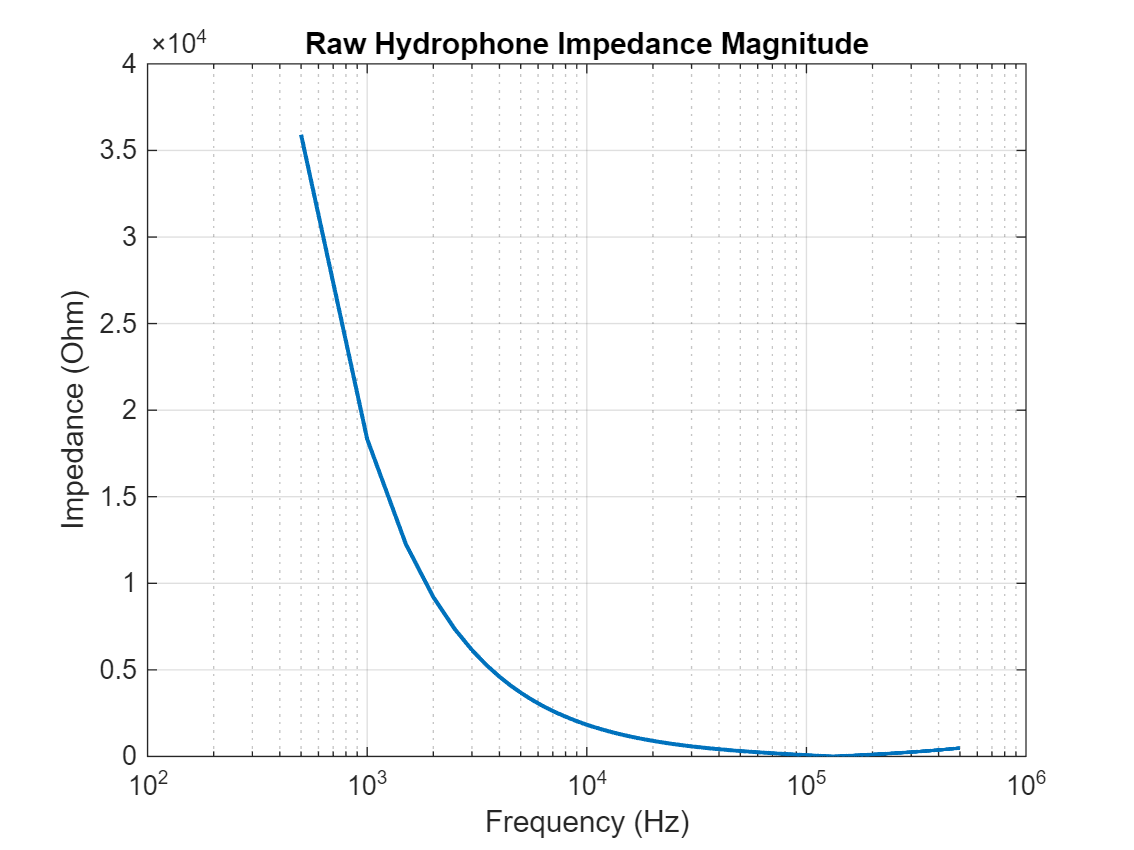


% The transfer function for one RC low-pass stage:
H_RC = @(w) 1./(1 + 1j*w*R_filter*C_filter);
% Two cascaded stages (2nd order):
H_filter = @(w) (H_RC(w)).^2;


%% ===== Define Overall Transfer Functions =====
% (A) RAW HYDROPHONE (without matching or filtering)
H_raw = @(w) hydrophone_Z(w) ./ (R_source + hydrophone_Z(w));

% (B) FILTERED & MATCHED CHAIN
% Here we include the voltage divider effect of the driver with the effective load
% (i.e. matching element + hydrophone) and then apply the RC filter.
H_total = @(w) H_filter(w) .* H_matched(w);


%% ===== Frequency Domain Simulation Setup =====
fs = 1e6;         % Sampling frequency (Hz) for simulation
T  = 2e-3;        % Total simulation time (sec)
t  = 0:1/fs:T;    
N  = length(t);
if mod(N,2)~=0    % Force even number of samples
    N = N - 1;
    t = t(1:N);
end

% Driver input: Since your driver produces ±12 V on its two outputs (i.e. a 24 V differential swing)
% we can model an equivalent single-ended input as a square wave swinging from -12 V to +12 V.
Vsource = 5;
Qdrive = 3;
Vin = Vsource*Qdrive * square(2*pi*f0*t);  % This yields ±12 V.

% (In your actual circuit, you’d implement two identical RC filters (one for each rail)
% and then use a differential (e.g., transformer or balun) network. Here we simulate a 
% single-ended equivalent for simplicity.)

% Frequency vector for FFT (unique bins):
f_pos = (0:(N/2)) * fs/N;
w_pos = 2*pi*f_pos;


%% ===== Reconstruct Full FFT Transfer Functions =====
% Evaluate the transfer functions at the unique (positive-frequency) points:
H_raw_vals   = H_raw(w_pos);
H_total_vals = H_total(w_pos);

% Reconstruct full spectra with Hermitian symmetry:
H_raw_full   = [H_raw_vals, conj(H_raw_vals(end-1:-1:2))];
H_total_full = [H_total_vals, conj(H_total_vals(end-1:-1:2))];

% Compute FFT of the input signal:
Vin_fft = fft(Vin);

% Compute output signals by multiplying the FFT of Vin by the transfer functions:
Vout_raw_fft   = Vin_fft .* H_raw_full;
Vout_total_fft = Vin_fft .* H_total_full;
Vout_raw       = real(ifft(Vout_raw_fft));
Vout_total     = real(ifft(Vout_total_fft));

% For spectrum (single-sided):
Vraw_spec   = abs(Vout_raw_fft(1:N/2+1));
Vtotal_spec = abs(Vout_total_fft(1:N/2+1));


%% ===== Impedance vs. Frequency Plots =====
% We now plot the effective impedance (magnitude & phase) as “seen” by the driver,
% before and after the filtering network. For the raw case, we plot hydrophone_Z(w).
% For the filtered case, we compute the effective impedance of the RC filter + matching
% network by “backing out” the voltage divider.
% 
% One simple approach is to compute the overall transfer function H_total(w)
% and then infer the effective load impedance Z_eff using:
%   H = Z_eff/(R_source + Z_eff)  =>  Z_eff = H*R_source/(1 - H)
% (Note: This is valid only when H is less than one, and it represents the net load
% impedance “seen” by the driver.)
%
% Here, we perform this calculation only at each frequency for comparison.

% Raw effective impedance:
Z_raw_vals = hydrophone_Z(w_pos);  % directly the sensor’s impedance

% For the filtered & matched chain, the overall voltage divider is H_total = Z_eff/(R_source+Z_eff)
% Solve for Z_eff:
Z_eff_vals = H_total_vals .* R_source ./ (1 - H_total_vals + eps);  % add eps to avoid div-by-zero

%% --- Plot Impedances (Magnitude & Phase) ---
figure;
semilogx(f_pos, abs(Z_raw_vals), 'LineWidth', 1.5);
title('Raw Hydrophone Impedance Magnitude');
xlabel('Frequency (Hz)');
ylabel('Impedance (Ohm)'); grid on;

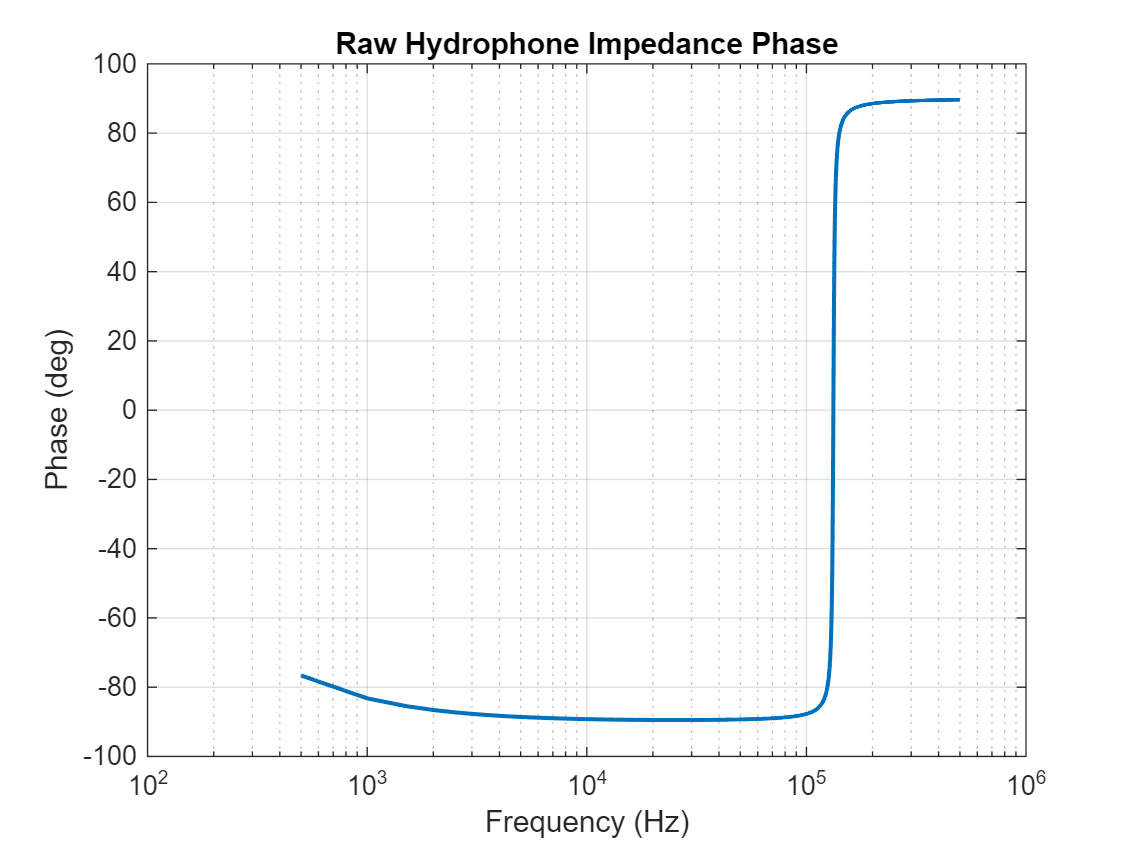


figure;
semilogx(f_pos, rad2deg(angle(Z_raw_vals)), 'LineWidth', 1.5);
title('Raw Hydrophone Impedance Phase');
xlabel('Frequency (Hz)');
ylabel('Phase (deg)'); grid on;

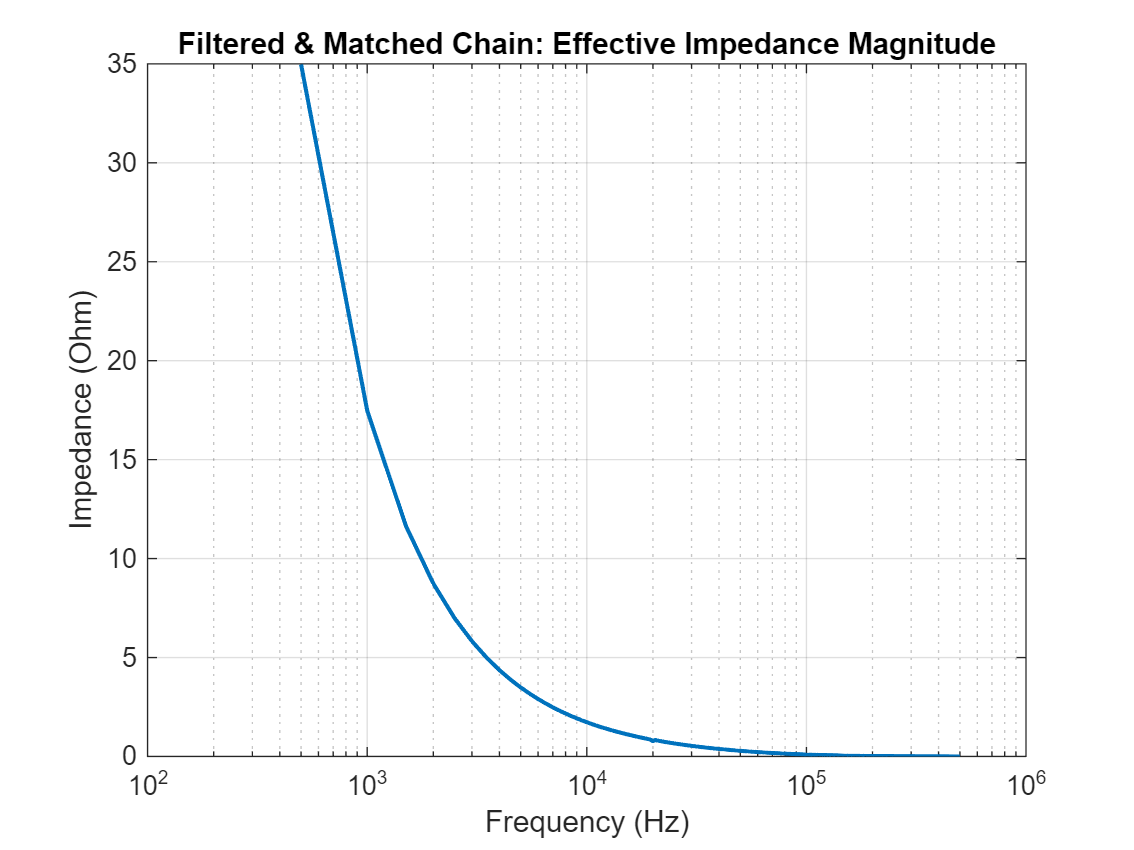



%% --- Plot Filtered & Matched (Effective) Impedance (Magnitude & Phase) ---
figure;
semilogx(f_pos, abs(Z_eff_vals), 'LineWidth', 1.5);
title('Filtered & Matched Chain: Effective Impedance Magnitude');
xlabel('Frequency (Hz)');
ylabel('Impedance (Ohm)'); grid on;

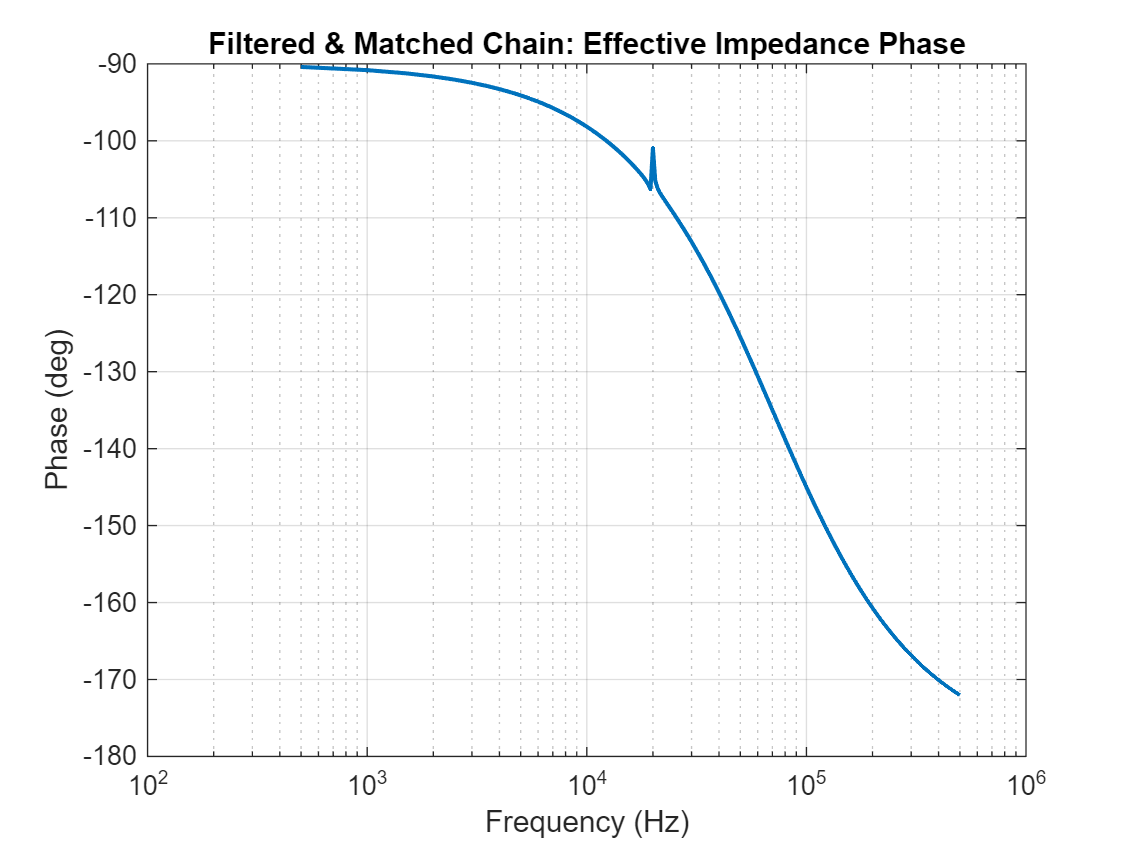


figure;
semilogx(f_pos, rad2deg(angle(Z_eff_vals)), 'LineWidth', 1.5);
title('Filtered & Matched Chain: Effective Impedance Phase');
xlabel('Frequency (Hz)');
ylabel('Phase (deg)'); grid on;

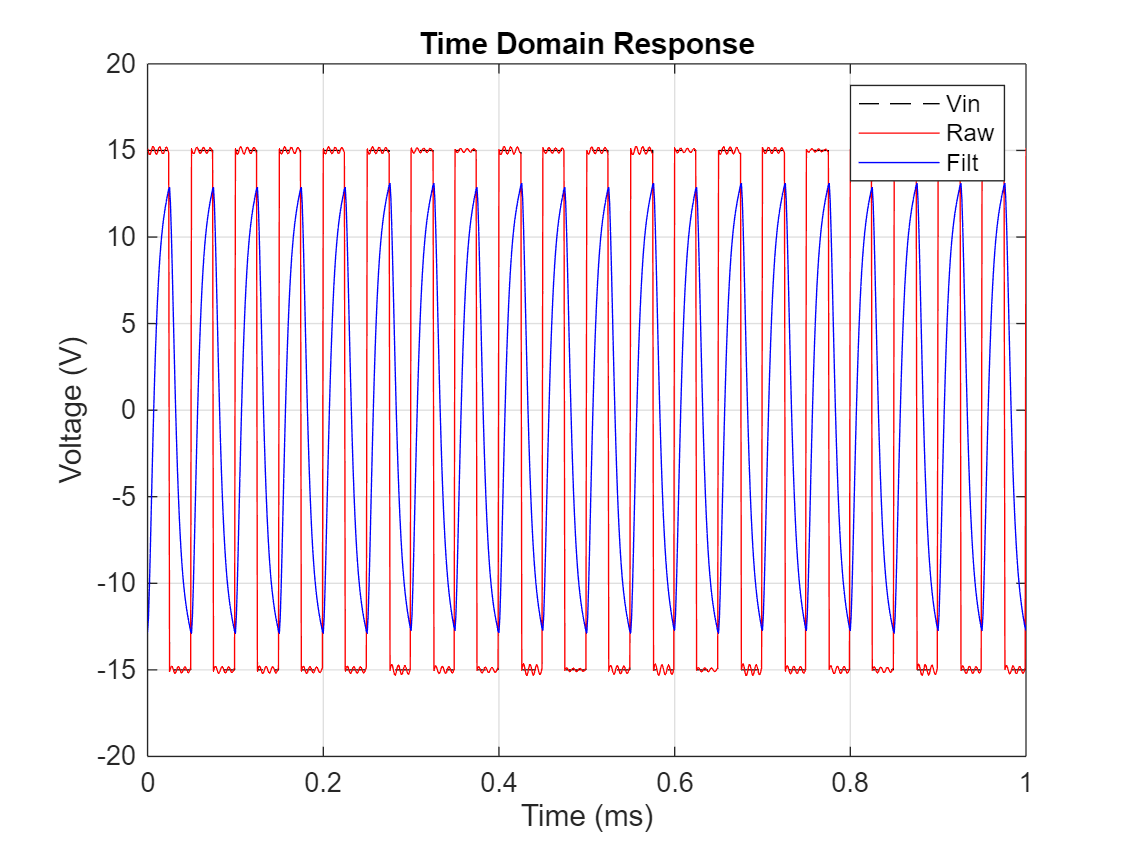


%% ===== Time-Domain, Spectrum, and Transfer Function Plots =====
% --- Raw Hydrophone ---
figure;
plot(t*1e3, Vin, 'k--', "DisplayName", "Vin"); hold on;
plot(t*1e3, Vout_raw, 'r', "DisplayName", "Raw");
plot(t*1e3, Vout_total, 'b', "DisplayName", "Filt");
xlim([0 1])
title('Time Domain Response');
legend
xlabel('Time (ms)'); ylabel('Voltage (V)'); grid on;

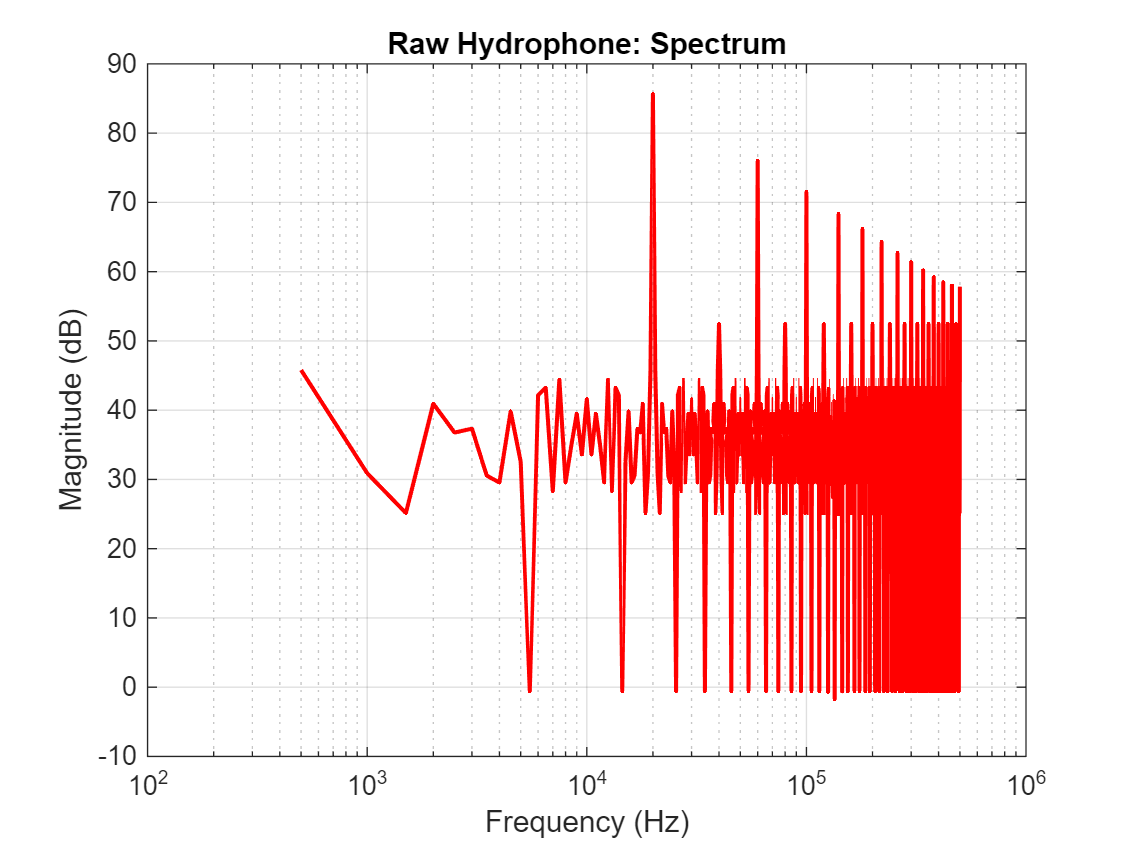


figure;
semilogx(f_pos, 20*log10(Vraw_spec+eps), 'r','LineWidth',1.5);
title('Raw Hydrophone: Spectrum');
xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)'); grid on;

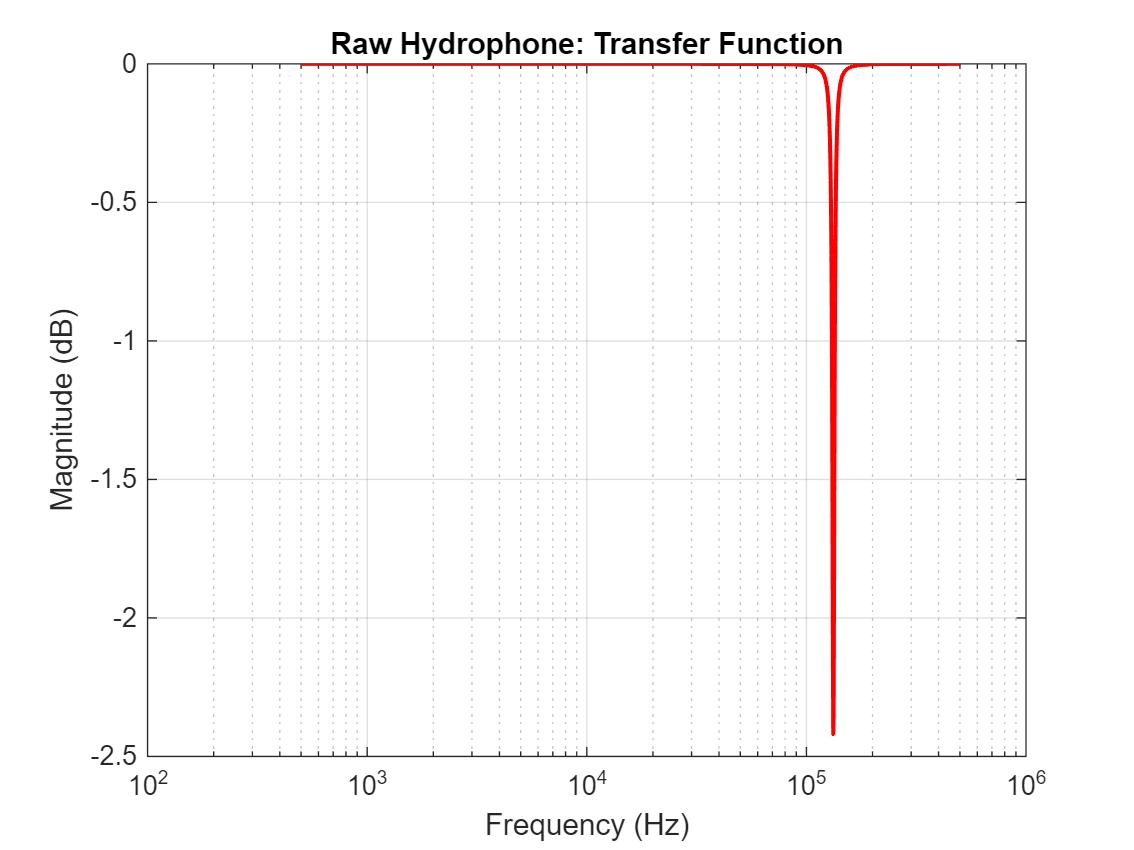


figure;
semilogx(f_pos, 20*log10(abs(H_raw_vals)+eps), 'r','LineWidth',1.5);
title('Raw Hydrophone: Transfer Function');
xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)'); grid on;

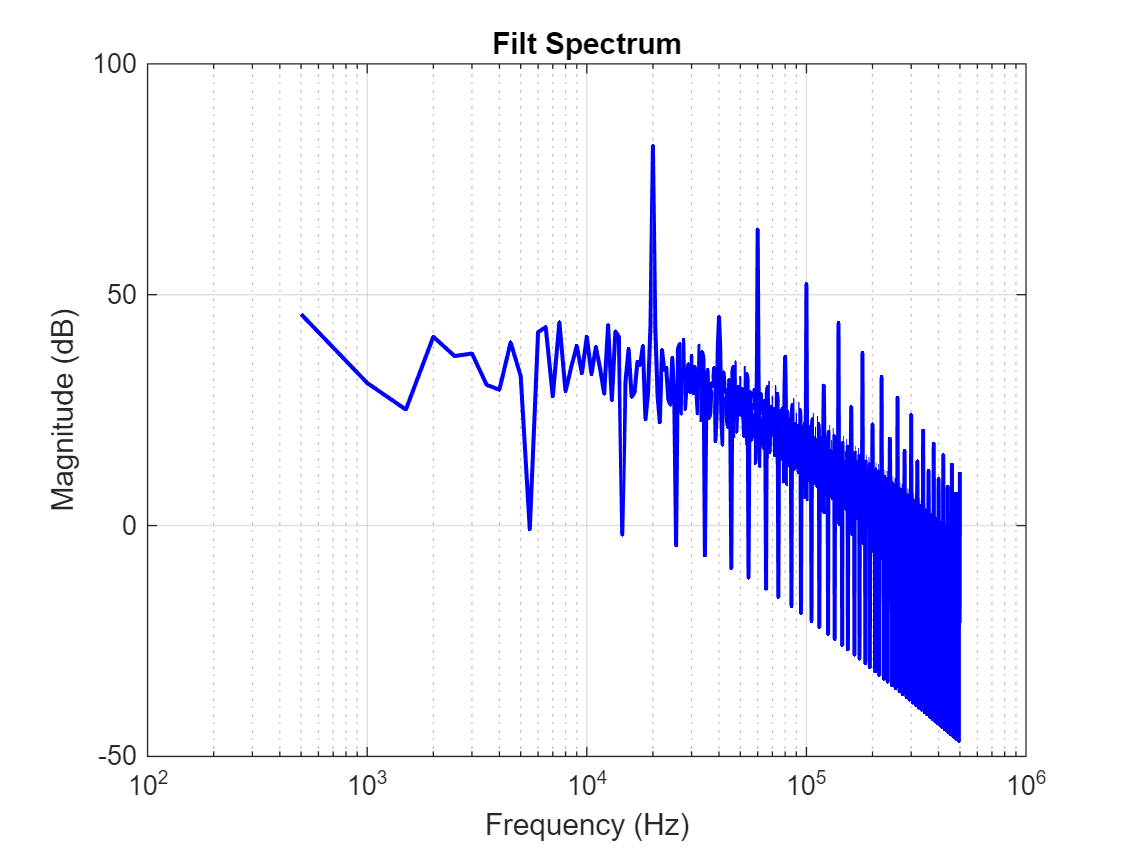

% 
% 
% % --- Filtered & Matched Chain ---
% figure;
% plot(t*1e3, Vin, 'k--'); hold on;
% plot(t*1e3, Vout_total, 'b');
% title('Filtered & Matched: Time Domain Response');
% xlim([0 1])
% xlabel('Time (ms)'); ylabel('Voltage (V)'); grid on;
% 
figure;
semilogx(f_pos, 20*log10(Vtotal_spec+eps), 'b','LineWidth',1.5);
title('Filt Spectrum');
xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)'); grid on;

% 
% figure;
% semilogx(f_pos, 20*log10(abs(H_total_vals)+eps), 'b','LineWidth',1.5);
% title('Filtered & Matched: Transfer Function');
% xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)'); grid on;
